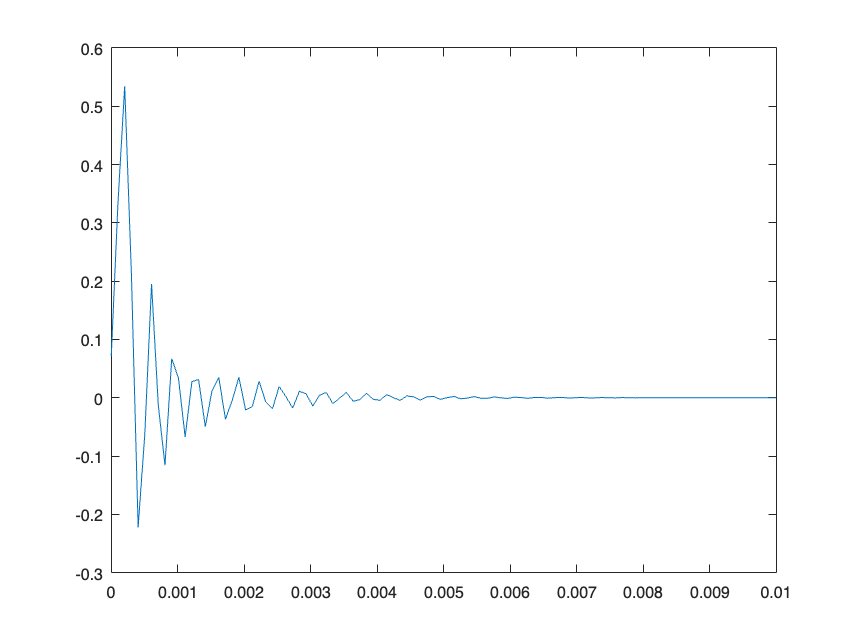

fc = 100e3;
fs = 1e6;
rp = 1;
% x: input signal
% y: filtered output signal

% Calculate analog cutoff frequency and convert to digital
wc = 2*pi*fc; % analog cutoff frequency
wd = 2*pi*fc/fs; % digital cutoff frequency

% Design Chebyshev Type I filter coefficients
[n, Wn] = cheb1ord(wd, 0.5*wd, rp, 60);
[b, a] = cheby1(n, rp, Wn);


L = 1e-2;
N_L = 100;
t = linspace(0, L, N_L); % delta function
x = [1, zeros(1, N_L-1)];

% Filter input signal using the filter coefficients
y = filter(b, a, x);
% Calculate frequency response
[H, w] = freqz(b, a, N_L);

figure
plot(t, y)

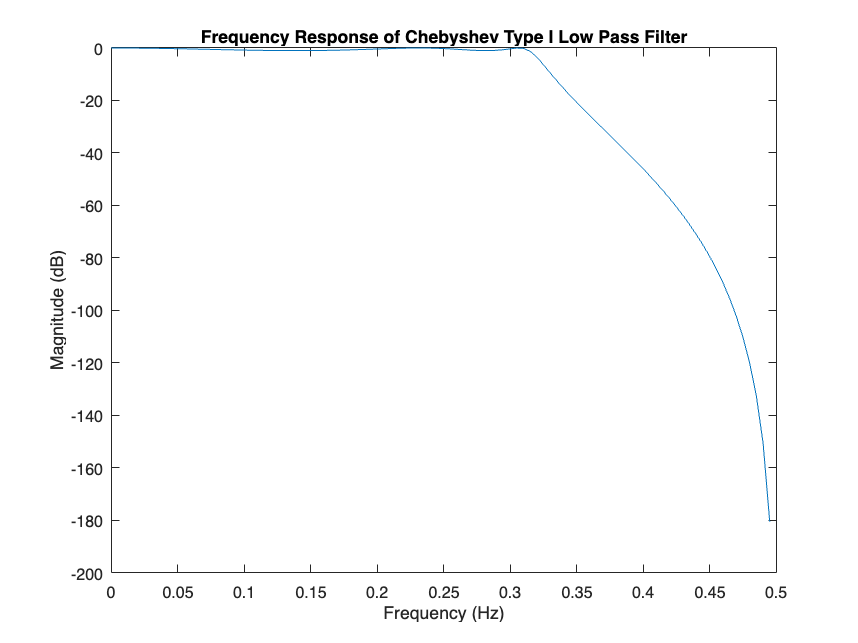


% Plot frequency response
figure;
plot(w/(2*pi), 20*log10(abs(H)));
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Frequency Response of Chebyshev Type I Low Pass Filter');

New

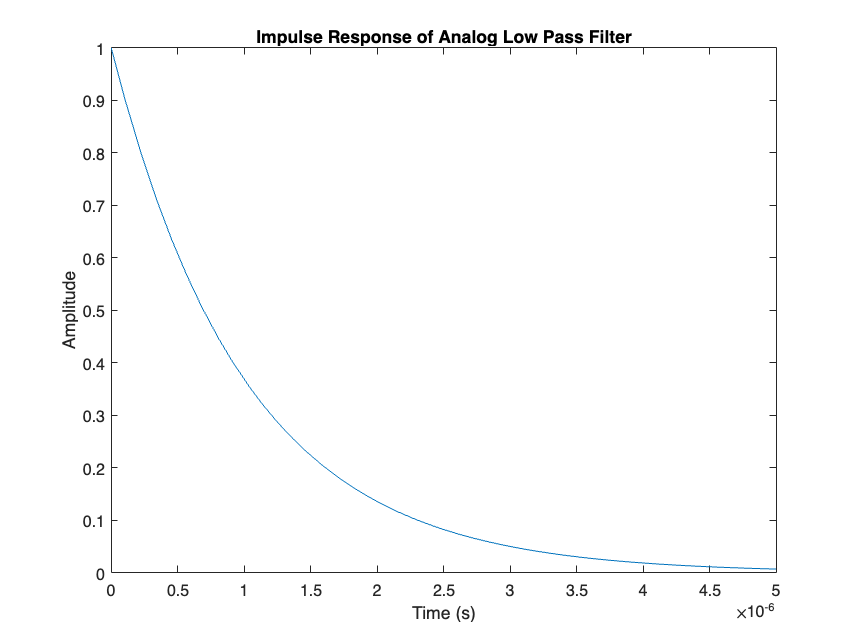

% Define the filter parameters
R = 1;      % Resistance in ohms
C = 1e-6;   % Capacitance in farads
fc = 1/(2*pi*R*C);  % Cutoff frequency in Hz

% Create the transfer function H(s)
syms s
H = (1/(2*pi*fc))/(1 + s/(2*pi*fc));

% Find the impulse response Gamma(t)
syms t
Gamma_t = ilaplace(H);

% Plot the impulse response
figure
fplot(Gamma_t, [0, 5*R*C]);
xlabel('Time (s)');
ylabel('Amplitude');
title('Impulse Response of Analog Low Pass Filter');

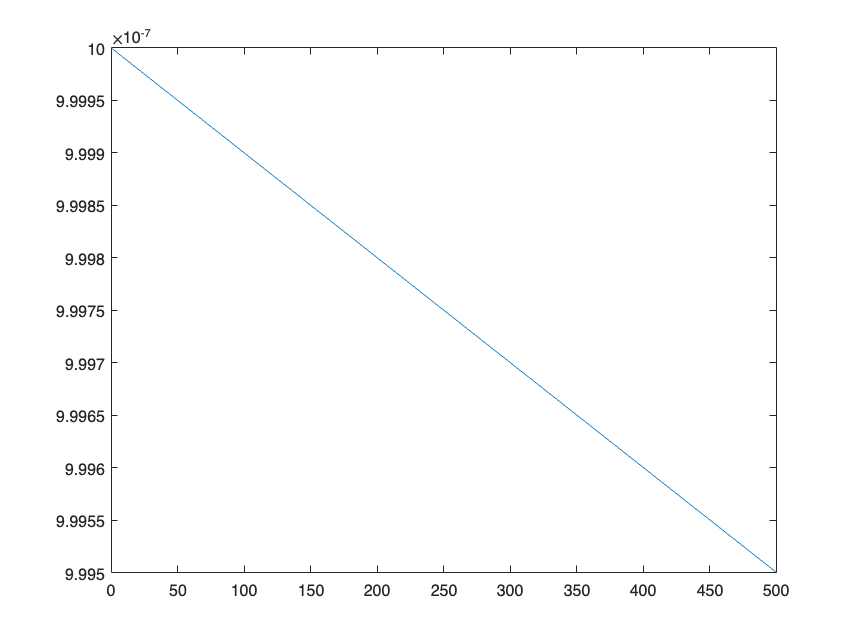

figure
fplot(H, [0, 500])

ODE

clear all
a = rand(1, 256); % generate a random array of length 256
b = rand(1, 256); % generate another random array of length 256

% define the ODE as a function handle
odefun = @(t, v) a.*v - b;

% set the initial condition
v0 = zeros(1, 256);

% define the time span
tspan = [0 1];

% solve the ODE using ode45
[t, v] = ode45(odefun, tspan, v0);

Error using odearguments
@(T,V)A.*V-B must return a column vector.

Error in ode45 (line 107)
    odearguments(odeIsFuncHandle,odeTreatAsMFile, solver_name, ode, tspan, y0, options, varargin);


% plot the solution
plot(t, v);
xlabel('Time');
ylabel('v(t)');
